%This livescript intend to visualize the sampling of the tstat and ß
%images. The script works with the output of the sampling function
%BK_layer_sampling_pain_study_pipeline (see the function how to call)

% figure('Position',[100, 100, 2400, 1200]);
plotidx=0;
allsubj={7349, 7356, 7361, 7375, 7376,...
         7383, 7402, 7403, 7404,...
         7405, 7408, 7414, 7415,...
         7425, 7426, 7433, 7434,...
         7435, 7443, 7444, 7445,...
         7448, 7449, 7452, 7453,...
         7454, 7455, 7456, 7457,...
         7468, 7469, 7482, 7484, 7485}; %34subj 7349 output was too big-->not safed and need to rerun, and 7356 has no good orientation was not run at all.32 is visualized now
% subjready={7403,7404,7444, 7484}
% subjready={7375, 7361, 7376,7383, 7402, 7403, 7404,7405, 7408, 7414, 7415};
subplotsize=[8 4];
% disp('This is the distribution of the indiviudal T value(across columns) for the three contrast')
allsubjlayer={};
subjidx=0;
td=[];
bu=[];
topdown=cell(2,1);
bottomup=cell(2,1);
for subj=allsubj%{7414,7482,7484,7485}
    roipath='C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\';
    processedimgfile=[roipath num2str(subj{:}) '\functionalmasks\interimdata_rwls_S2tstat.mat']; %I renamed to derived the output for the other ROI as it reflects more the content of that .mat file 
    %it has the follwoing output:
    %{1,1} cell: 2 cells, each for one side(left+right): vertex*image of the "columnarvalue"(deeper 75% of the column mean) 
    %{1,2} cell: 2 cells, each for one side(left+right): vertex*layer*image of the laminar value
    %{1,3} cell: 2 cells,each for one side(left+right): the depth of each "column"
    %{1,4} cell: the list of sampled images 
    if exist(processedimgfile,"file")
        processedimg=load(processedimgfile);
%         [columnspecificts,layeractivation,allroicolumnsize,sampled_img_list]
        disp([num2str(subj{:}) ' subject columnar info r'])
        nROI=length(processedimg.interimdata_columns{1,1});
        tthrs=1;
        topcolumnnumber=200; %200 or 100?
        subjidx=subjidx+1;
        plotidx=plotidx+1;
        allsubjid(plotidx)=subj{:};
        for ROI=1:nROI
            %based on t value
%             conjugationcolumnarstat=min([processedimg.interimdata_columns{1,1}{ROI,1}(:,3)*(-1),processedimg.interimdata_columns{1,1}{ROI,1}(:,4)],[],2); %3-cognition but need to be reversed!!,4-pain
            %based on ßmap
            conjugationcolumnarstat=min([processedimg.interimdata_columns{1,1}{ROI,1}(:,1)*(-1),processedimg.interimdata_columns{1,1}{ROI,1}(:,2)],[],2); %3-cognition but need to be reversed!!,4-pain
            
            
            numberofcolumnsinmask=length(conjugationcolumnarstat);
                    
            numberofactcolumnsbasedonconj=sum(conjugationcolumnarstat>tthrs);
                    
            disp(['Subject:' subj{:} 'The number of columns within the funcitonal mask: ',num2str(numberofcolumnsinmask)])
            
            disp(['Subject:' subj{:} 'The number of columns acitvating in each run(t>', num2str(tthrs), ') for cognition AND pain: ',num2str(numberofactcolumnsbasedonconj)])

            [top200Values, top200Indices] =maxk(conjugationcolumnarstat,topcolumnnumber);
            positiveIndices = top200Indices(top200Values > 0);
            % Check if any negative values were removed
            if length(positiveIndices) < topcolumnnumber
                warning('The top 200 values contained negative numbers. Only %d positive values are retained.', length(positiveIndices));
            end
            subj_td=mean(processedimg.interimdata_columns{1,2}{ROI,1}(positiveIndices,:,1)*(-1),1,'omitnan');%main effect of cognition but need to be reversed!!!;
            subj_bu=mean(processedimg.interimdata_columns{1,2}{ROI,1}(positiveIndices,:,2),1,'omitnan'); %main effect of pain

            topdown{ROI}=vertcat(topdown{ROI},subj_td);
%             td=topdown{ROI};
            bottomup{ROI}=vertcat(bottomup{ROI},subj_bu);
%             bu=bottomup{ROI};
        end 
    else
        disp([num2str(subj{:}) ' subject has  no sampled cluster'])
    end

end

7349 subject has  no sampled cluster
7356 subject has  no sampled cluster


7361 subject columnar info r


Subject:᳁The number of columns within the funcitonal mask: 2835


Subject:᳁The number of columns acitvating in each run(t>1) for cognition AND pain: 213


Subject:᳁The number of columns within the funcitonal mask: 3338


Subject:᳁The number of columns acitvating in each run(t>1) for cognition AND pain: 344


7375 subject columnar info r


Subject:᳏The number of columns within the funcitonal mask: 2826


Subject:᳏The number of columns acitvating in each run(t>1) for cognition AND pain: 510


Subject:᳏The number of columns within the funcitonal mask: 4402


Subject:᳏The number of columns acitvating in each run(t>1) for cognition AND pain: 695


7376 subject columnar info r


Subject:᳐The number of columns within the funcitonal mask: 2541


Subject:᳐The number of columns acitvating in each run(t>1) for cognition AND pain: 222


Subject:᳐The number of columns within the funcitonal mask: 4608


Subject:᳐The number of columns acitvating in each run(t>1) for cognition AND pain: 393


7383 subject columnar info r


Subject:᳗The number of columns within the funcitonal mask: 2884


Subject:᳗The number of columns acitvating in each run(t>1) for cognition AND pain: 186


Subject:᳗The number of columns within the funcitonal mask: 3809


Subject:᳗The number of columns acitvating in each run(t>1) for cognition AND pain: 464


7402 subject columnar info r


Subject:ᳪThe number of columns within the funcitonal mask: 5230


Subject:ᳪThe number of columns acitvating in each run(t>1) for cognition AND pain: 520


Subject:ᳪThe number of columns within the funcitonal mask: 7545


Subject:ᳪThe number of columns acitvating in each run(t>1) for cognition AND pain: 595


7403 subject columnar info r


Subject:ᳫThe number of columns within the funcitonal mask: 2138


Subject:ᳫThe number of columns acitvating in each run(t>1) for cognition AND pain: 117


Subject:ᳫThe number of columns within the funcitonal mask: 3405


Subject:ᳫThe number of columns acitvating in each run(t>1) for cognition AND pain: 147


7404 subject columnar info r


Subject:ᳬThe number of columns within the funcitonal mask: 2107


Subject:ᳬThe number of columns acitvating in each run(t>1) for cognition AND pain: 215


Subject:ᳬThe number of columns within the funcitonal mask: 3318


Subject:ᳬThe number of columns acitvating in each run(t>1) for cognition AND pain: 479


7405 subject columnar info r


Subject:᳭The number of columns within the funcitonal mask: 1632


Subject:᳭The number of columns acitvating in each run(t>1) for cognition AND pain: 278


Subject:᳭The number of columns within the funcitonal mask: 3072


Subject:᳭The number of columns acitvating in each run(t>1) for cognition AND pain: 425


7408 subject columnar info r


Subject:ᳰThe number of columns within the funcitonal mask: 2195


Subject:ᳰThe number of columns acitvating in each run(t>1) for cognition AND pain: 147


Subject:ᳰThe number of columns within the funcitonal mask: 4119


Subject:ᳰThe number of columns acitvating in each run(t>1) for cognition AND pain: 280


7414 subject columnar info r


Subject:ᳶThe number of columns within the funcitonal mask: 2191


Subject:ᳶThe number of columns acitvating in each run(t>1) for cognition AND pain: 239


Subject:ᳶThe number of columns within the funcitonal mask: 3764


Subject:ᳶThe number of columns acitvating in each run(t>1) for cognition AND pain: 468


7415 subject columnar info r


Subject:᳷The number of columns within the funcitonal mask: 2148


Subject:᳷The number of columns acitvating in each run(t>1) for cognition AND pain: 80


Subject:᳷The number of columns within the funcitonal mask: 3728


Subject:᳷The number of columns acitvating in each run(t>1) for cognition AND pain: 184


7425 subject columnar info r


Subject:ᴁThe number of columns within the funcitonal mask: 2061


Subject:ᴁThe number of columns acitvating in each run(t>1) for cognition AND pain: 100


Subject:ᴁThe number of columns within the funcitonal mask: 4017


Subject:ᴁThe number of columns acitvating in each run(t>1) for cognition AND pain: 106


7426 subject columnar info r


Subject:ᴂThe number of columns within the funcitonal mask: 2128


Subject:ᴂThe number of columns acitvating in each run(t>1) for cognition AND pain: 195


Subject:ᴂThe number of columns within the funcitonal mask: 3549


Subject:ᴂThe number of columns acitvating in each run(t>1) for cognition AND pain: 377


7433 subject columnar info r


Subject:ᴉThe number of columns within the funcitonal mask: 2638


Subject:ᴉThe number of columns acitvating in each run(t>1) for cognition AND pain: 176


Subject:ᴉThe number of columns within the funcitonal mask: 4528


Subject:ᴉThe number of columns acitvating in each run(t>1) for cognition AND pain: 342


7434 subject columnar info r


Subject:ᴊThe number of columns within the funcitonal mask: 2195


Subject:ᴊThe number of columns acitvating in each run(t>1) for cognition AND pain: 270


Subject:ᴊThe number of columns within the funcitonal mask: 4214


Subject:ᴊThe number of columns acitvating in each run(t>1) for cognition AND pain: 558


7435 subject columnar info r


Subject:ᴋThe number of columns within the funcitonal mask: 1845


Subject:ᴋThe number of columns acitvating in each run(t>1) for cognition AND pain: 109


Subject:ᴋThe number of columns within the funcitonal mask: 3106


Subject:ᴋThe number of columns acitvating in each run(t>1) for cognition AND pain: 242


7443 subject columnar info r


Subject:ᴓThe number of columns within the funcitonal mask: 2792


Subject:ᴓThe number of columns acitvating in each run(t>1) for cognition AND pain: 238


Subject:ᴓThe number of columns within the funcitonal mask: 4620


Subject:ᴓThe number of columns acitvating in each run(t>1) for cognition AND pain: 502


7444 subject columnar info r


Subject:ᴔThe number of columns within the funcitonal mask: 2593


Subject:ᴔThe number of columns acitvating in each run(t>1) for cognition AND pain: 347


Subject:ᴔThe number of columns within the funcitonal mask: 4791


Subject:ᴔThe number of columns acitvating in each run(t>1) for cognition AND pain: 862


7445 subject columnar info r


Subject:ᴕThe number of columns within the funcitonal mask: 2588


Subject:ᴕThe number of columns acitvating in each run(t>1) for cognition AND pain: 171


Subject:ᴕThe number of columns within the funcitonal mask: 4827


Subject:ᴕThe number of columns acitvating in each run(t>1) for cognition AND pain: 539


7448 subject columnar info r


Subject:ᴘThe number of columns within the funcitonal mask: 1712


Subject:ᴘThe number of columns acitvating in each run(t>1) for cognition AND pain: 338


Subject:ᴘThe number of columns within the funcitonal mask: 3179


Subject:ᴘThe number of columns acitvating in each run(t>1) for cognition AND pain: 540


7449 subject columnar info r


Subject:ᴙThe number of columns within the funcitonal mask: 2155


Subject:ᴙThe number of columns acitvating in each run(t>1) for cognition AND pain: 148


Subject:ᴙThe number of columns within the funcitonal mask: 3965


Subject:ᴙThe number of columns acitvating in each run(t>1) for cognition AND pain: 335


7452 subject columnar info r


Subject:ᴜThe number of columns within the funcitonal mask: 1704


Subject:ᴜThe number of columns acitvating in each run(t>1) for cognition AND pain: 94


Subject:ᴜThe number of columns within the funcitonal mask: 3209


Subject:ᴜThe number of columns acitvating in each run(t>1) for cognition AND pain: 328


7453 subject columnar info r


Subject:ᴝThe number of columns within the funcitonal mask: 1760


Subject:ᴝThe number of columns acitvating in each run(t>1) for cognition AND pain: 234


Subject:ᴝThe number of columns within the funcitonal mask: 3689


Subject:ᴝThe number of columns acitvating in each run(t>1) for cognition AND pain: 376


7454 subject columnar info r


Subject:ᴞThe number of columns within the funcitonal mask: 2018


Subject:ᴞThe number of columns acitvating in each run(t>1) for cognition AND pain: 244


Subject:ᴞThe number of columns within the funcitonal mask: 3485


Subject:ᴞThe number of columns acitvating in each run(t>1) for cognition AND pain: 569


7455 subject columnar info r


Subject:ᴟThe number of columns within the funcitonal mask: 1904


Subject:ᴟThe number of columns acitvating in each run(t>1) for cognition AND pain: 135


Subject:ᴟThe number of columns within the funcitonal mask: 3078


Subject:ᴟThe number of columns acitvating in each run(t>1) for cognition AND pain: 314


7456 subject columnar info r


Subject:ᴠThe number of columns within the funcitonal mask: 1922


Subject:ᴠThe number of columns acitvating in each run(t>1) for cognition AND pain: 192


Subject:ᴠThe number of columns within the funcitonal mask: 3798


Subject:ᴠThe number of columns acitvating in each run(t>1) for cognition AND pain: 450


7457 subject columnar info r


Subject:ᴡThe number of columns within the funcitonal mask: 2330


Subject:ᴡThe number of columns acitvating in each run(t>1) for cognition AND pain: 249


Subject:ᴡThe number of columns within the funcitonal mask: 3567


Subject:ᴡThe number of columns acitvating in each run(t>1) for cognition AND pain: 383


7468 subject columnar info r


Subject:ᴬThe number of columns within the funcitonal mask: 1595


Subject:ᴬThe number of columns acitvating in each run(t>1) for cognition AND pain: 134


Subject:ᴬThe number of columns within the funcitonal mask: 3012


Subject:ᴬThe number of columns acitvating in each run(t>1) for cognition AND pain: 248


7469 subject columnar info r


Subject:ᴭThe number of columns within the funcitonal mask: 2537


Subject:ᴭThe number of columns acitvating in each run(t>1) for cognition AND pain: 349


Subject:ᴭThe number of columns within the funcitonal mask: 3639


Subject:ᴭThe number of columns acitvating in each run(t>1) for cognition AND pain: 611


7482 subject columnar info r


Subject:ᴺThe number of columns within the funcitonal mask: 2046


Subject:ᴺThe number of columns acitvating in each run(t>1) for cognition AND pain: 168


Subject:ᴺThe number of columns within the funcitonal mask: 3335


Subject:ᴺThe number of columns acitvating in each run(t>1) for cognition AND pain: 292


7484 subject columnar info r


Subject:ᴼThe number of columns within the funcitonal mask: 1840


Subject:ᴼThe number of columns acitvating in each run(t>1) for cognition AND pain: 202


Subject:ᴼThe number of columns within the funcitonal mask: 3506


Subject:ᴼThe number of columns acitvating in each run(t>1) for cognition AND pain: 552


7485 subject columnar info r


Subject:ᴽThe number of columns within the funcitonal mask: 2102


Subject:ᴽThe number of columns acitvating in each run(t>1) for cognition AND pain: 288


Subject:ᴽThe number of columns within the funcitonal mask: 3877


Subject:ᴽThe number of columns acitvating in each run(t>1) for cognition AND pain: 600


nproc=2;
nsubj=length(allsubjid);
nside=2;

td=array2table([topdown{1};topdown{2}],'VariableNames',strcat("layer",string(1:20)));
td.process=repmat("topdown",nsubj*nside,1);
td.side=[repmat("left",nsubj,1);repmat("right",nsubj,1)];

bu=array2table([bottomup{1};bottomup{2}],'VariableNames',strcat("layer",string(1:20)));
bu.process=repmat("bottomup",nsubj*nside,1);
bu.side=[repmat("left",nsubj,1);repmat("right",nsubj,1)];

s2=[td;bu];

s2.subjid=string(repmat(allsubjid',nproc*nside,1));
% s1.subjid=string(repmat(allsubjid',nproc,1));
pathtooutput='C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\layerdata\';

writetable(s2,[ pathtooutput 'S2_derived_layervalues.csv'])
% writematrix(allsubjid',[pathtooutput 'S1_subjid.csv'])


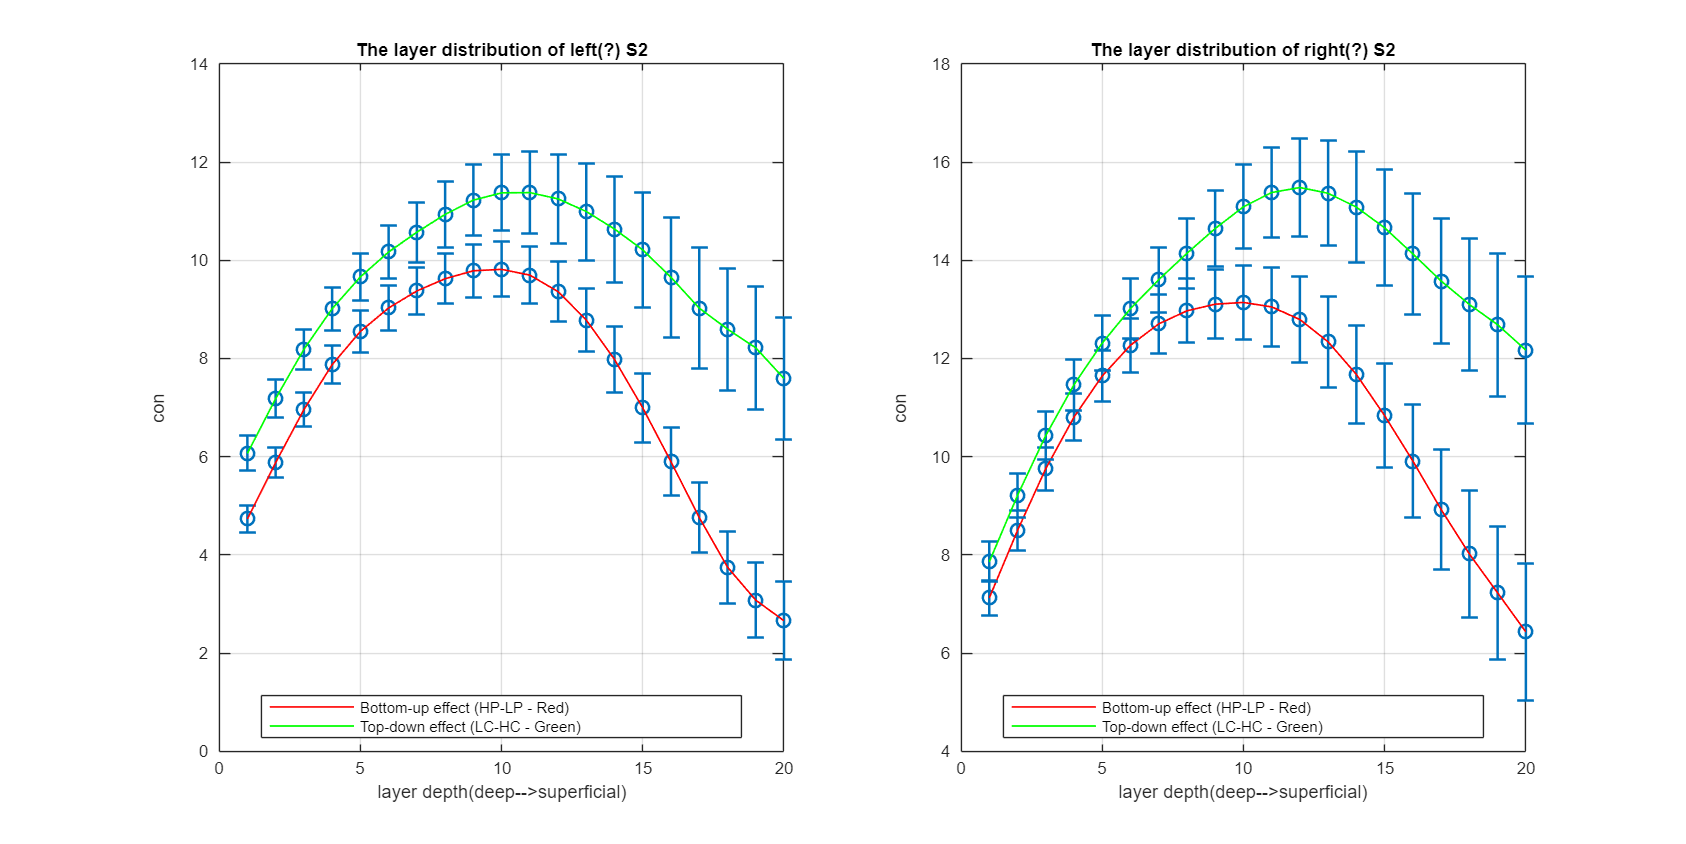

figure('Position',[100, 100, 2400, 1200]);

% alldataroi2_bet={bottomup_t,topdown_t};
for roitype=1:2
    alldata={bottomup{roitype,1}, topdown{roitype,1}};
    if roitype==1
    %             data=alldataroi1_beta{dataidx};
        titlenm='The layer distribution of left(?) S2';
        
    elseif roitype==2
    %             data=alldataroi2_bet{dataidx};
        titlenm='The layer distribution of right(?) S2';
        
    end
    for dataidx=1:2
        % Calculate column-wise mean and standard error

        data=alldata{dataidx};
        ylabltxt='con';
        columnMeans = mean(data, 1); % Mean of each column
        columnStdErrors = std(data, 0, 1) ./ sqrt(size(data, 1)); % Standard error
        subplot(1,2,roitype)
        % Create the scatter plot
%         legend('Bottom-up affect (main eff of pain - Red)','Top-down (main effect of cognition - Blue)', 'Location', 'south');

        errorbar(1:20, columnMeans, columnStdErrors, ...
            'o', 'LineWidth', 1.5, 'MarkerSize', 8, 'Color', [0 0.4470 0.7410], 'CapSize', 10);
        hold on;
        
        % Connect the points with a line
        if dataidx==1
            lineHandle1 = plot(1:20, columnMeans, '-r', 'LineWidth', 1);
        else
            lineHandle2 = plot(1:20, columnMeans, '-g', 'LineWidth', 1);
        end

        % Customize the plot
        xlabel('layer depth(deep-->superficial)');
        ylabel(ylabltxt);
        % Add legend only for the lines
        
    %     label()
        title(titlenm);
        grid on;
        
    end
    legend([lineHandle1, lineHandle2], ...
        {'Bottom-up effect (HP-LP - Red)', ...
        'Top-down effect (LC-HC - Green)'}, ...
        'Location', 'south');
    hold off;
end